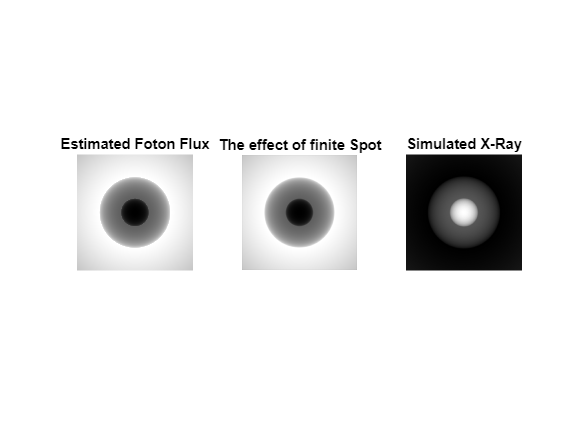

clear; clc;
% r is the distance between the center of the detector to any point in the
% film
% 
% the rect equation 
% rs = x*r/100  
%X1 intesection between rect and circle
%x = (500 (1600 - sqrt(5) sqrt(2000 - 51 r^2)))/(r^2 + 10000)
%X2 intesection between rect and circle
%x = (500 (sqrt(5) sqrt(2000 - 51 r^2) + 1600))/(r^2 + 10000)
% Comput distance between points pitagoras

% %%%%%%%%%%%%Constants

% Total Number of photons reaching the detector
No = 1.0e10;

% tissues radius (cm)

Ro = 5.0; %Soft tissue
Rh = 2.0; %Bone
Rm = 0.01; %Micro Calcification

% tissue atenuation (per cm)
m_s = 0.1; % Soft
m_h = 0.5; % Bone
m_m = 5.0; %Calcification

% Detector size (cm)
Lo = 20;
%Detector size in pixels
N= 1000;

%Distance between source and detector (cm)
D = 30;

% Center of soft tissue from source (cm)
Z = 25;

% Y Center of microcalcification from source (cm)
Ym = 2.0;

%Quantum efficiency
Q = 5.0;

%spot size (cm)

ss = 0.5;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Code

detector = ones(N)*No*Q/(N*N);

pixels_per_cm = N/Lo;


for i = 1:N
    for j = 1:N
        x = (j-N/2)/pixels_per_cm;
        y = (N/2-i)/pixels_per_cm;
        r = sqrt(x^2+y^2);
        dis = D^4 * Ro^2 + D^2 * r^2 * Ro^2 - D^2* r^2 * Z^2;
        dis2 = D^4 * Rh^2 + D^2 * r^2 * Rh^2 - D^2* r^2 * Z^2;
        xm = x;
        ym = y-D/Z*Ym;
        rm = sqrt(xm^2+ym^2);
        dis3 = D^4 * Rm^2 + D^2 * rm^2 * Rm^2 - D^2* rm^2 * Z^2;
        if (dis>0)
            x1 = (D^2*Z - sqrt(dis))/(r^2 + D^2);
            x2 = (D^2*Z + sqrt(dis))/(r^2 + D^2);
            r1 =  x1*r/D;
            r2 =  x2*r/D;
            lon = sqrt((x1-x2)^2+(r1-r2)^2);
            lon2 = 0;
            lon3 = 0;
            if (dis2 > 0)
                x1 = (D^2*Z - sqrt(dis2))/(r^2 + D^2);
                x2 = (D^2*Z + sqrt(dis2))/(r^2 + D^2);
                r1 =  x1*r/D;
                r2 =  x2*r/D;
                lon2 = sqrt((x1-x2)^2+(r1-r2)^2);
            end
            if (dis3 > 0)
                x1 = (D^2*Z - sqrt(dis3))/(rm^2 + D^2);
                x2 = (D^2*Z + sqrt(dis3))/(rm^2 + D^2);
                r1 =  x1*r/D;
                r2 =  x2*r/D;
                lon3 = sqrt((x1-x2)^2+(r1-r2)^2);
            end
            total = exp(-m_s*(lon-lon2-lon3)-m_h*lon2-m_m*lon3);
            detector(i,j) = total*detector(i,j);
        end
        coscubtheta = power(D/sqrt(r^2+D^2),3);
        detector(i,j) = detector(i,j)*coscubtheta;
    end
end
figure(1)

subplot(1,3,1);
imshow(detector,[]);
title("Estimated Foton Flux");

rdspot = (D-Z)/Z*ss;
rdpixspot = rdspot*pixels_per_cm;
imagespot = fspecial('disk',rdpixspot);
xrayimage = conv2(detector,imagespot,'same');

subplot(1,3,2);
imshow(xrayimage,[]);
title("The effect of finite Spot");

xrayimage = poissrnd(xrayimage);


subplot(1,3,3);
imshow(-(xrayimage),[]);
title("Simulated X-Ray");


% SNR CNR
mean_hueso=0;
mean_soft=0;
var_hueso=0;
var_soft=0;
area_hueso=0;
area_soft=0;
for i = 1:N
    for j = 1:N
        x = (j-N/2)/pixels_per_cm;
        y = (N/2-i)/pixels_per_cm;
        r = sqrt(x^2+y^2);
        dis = D^4 * Ro^2 + D^2 * r^2 * Ro^2 - D^2* r^2 * Z^2;
        dis2 = D^4 * Rh^2 + D^2 * r^2 * Rh^2 - D^2* r^2 * Z^2;
        if (dis>0)
            if (dis2 > 0)
                mean_hueso = mean_hueso + xrayimage(i,j);
                var_hueso = var_hueso + xrayimage(i,j).^2;
                area_hueso = area_hueso + 1;
            end
            if (dis2 < 0)
                mean_soft = mean_soft + xrayimage(i,j);
                var_soft = var_soft + xrayimage(i,j).^2;
                area_soft = area_soft + 1;
            end
        end
    end
end

mean_hueso = mean_hueso/area_hueso;
mean_soft = mean_soft/area_soft;
var_hueso = var_hueso/area_hueso - mean_hueso.^2;
var_soft = var_soft/area_soft - mean_soft.^2;

SNR = mean_soft/sqrt(var_soft);
CNR = (mean_soft-mean_hueso)/sqrt(var_soft);


%%% Detector PSF
imagespot = fspecial('gaussian',21,1);
xrayimage = conv2(xrayimage,imagespot,'valid');

subplot(1,3,3);
imshow(-log(xrayimage),[]);
title("Simulated X-Ray");